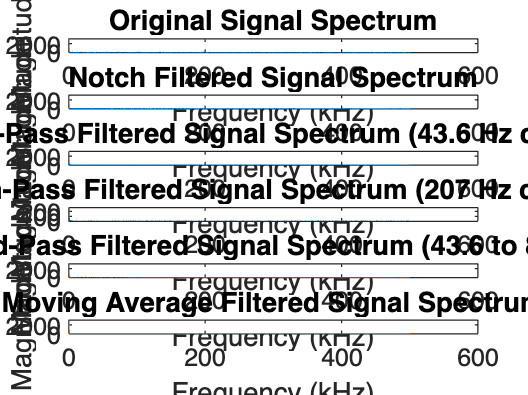

%% MATLAB Code: Filter 45 Hz vibration from 1 MHz sampled hydrogen deflagration data with Moving Average Analysis
clear, clc, close all
format short eng
% Load your data
load('E2038.mat');
data = pz(:,1);
% Parameters
Fs = fs; % Sampling frequency in Hz
fNoise = 45; % Noise frequency in Hz
Q = 30; % Quality factor (higher Q = narrower notch)

% Design notch filter
notchFilt = designfilt('bandstopiir', 'FilterOrder', 2, ...
    'HalfPowerFrequency1', fNoise - 2, 'HalfPowerFrequency2', fNoise + 2, ...
    'SampleRate', Fs);
% Apply the filter
dataFiltered = filtfilt(notchFilt, data);

% Design low-pass filter (cutoff at 45 Hz)
lowpassFilt = designfilt('lowpassiir', 'FilterOrder', 10, ...
    'HalfPowerFrequency', 1.95e3, 'SampleRate', Fs);
dataLowPass = filtfilt(lowpassFilt, data);

% Design high-pass filter (cutoff at 45 Hz)
highpassFilt = designfilt('highpassiir', 'FilterOrder', 4, ...
    'HalfPowerFrequency', 207, 'SampleRate', Fs);
dataHighPass = filtfilt(highpassFilt, data);

% Design band-pass filter (43.6 to 80 Hz)
bpfilt = designfilt('bandpassfir', ...
    'FilterOrder', 20, 'CutoffFrequency1', 43.6, ...
    'CutoffFrequency2', 80, 'SampleRate', Fs);
dataBandPass = filtfilt(bpfilt, data);

% Apply moving average filter
windowSize = 10000; % Adjust window size based on noise characteristics
dataMovingAvg = movmean(data, windowSize);

% Plot FFT before and after filtering
N = length(data);
f = linspace(0, Fs/2, floor(N/2));

% Compute FFTs
fftOriginal = abs(fft(data));
fftFiltered = abs(fft(dataFiltered));
fftLowPass = abs(fft(dataLowPass));
fftHighPass = abs(fft(dataHighPass));
fftBandPass = abs(fft(dataBandPass));
fftMovingAvg = abs(fft(dataMovingAvg));

figure;
subplot(6,1,1);
plot(f/1000, fftOriginal(1:floor(N/2)));
title('Original Signal Spectrum');
xlabel('Frequency (kHz)'); ylabel('Magnitude');

subplot(6,1,2);
plot(f/1000, fftFiltered(1:floor(N/2)));
title('Notch Filtered Signal Spectrum');
xlabel('Frequency (kHz)'); ylabel('Magnitude');

subplot(6,1,3);
plot(f/1000, fftLowPass(1:floor(N/2)));
title('Low-Pass Filtered Signal Spectrum (43.6 Hz cutoff)');
xlabel('Frequency (kHz)'); ylabel('Magnitude');

subplot(6,1,4);
plot(f/1000, fftHighPass(1:floor(N/2)));
title('High-Pass Filtered Signal Spectrum (207 Hz cutoff)');
xlabel('Frequency (kHz)'); ylabel('Magnitude');

subplot(6,1,5);
plot(f/1000, fftBandPass(1:floor(N/2)));
title('Band-Pass Filtered Signal Spectrum (43.6 to 80 Hz)');
xlabel('Frequency (kHz)'); ylabel('Magnitude');

subplot(6,1,6);
plot(f/1000, fftMovingAvg(1:floor(N/2)));
title('Moving Average Filtered Signal Spectrum');
xlabel('Frequency (kHz)'); ylabel('Magnitude');


disp('Filtering complete. Check the plots for noise reduction.');

Filtering complete. Check the plots for noise reduction.


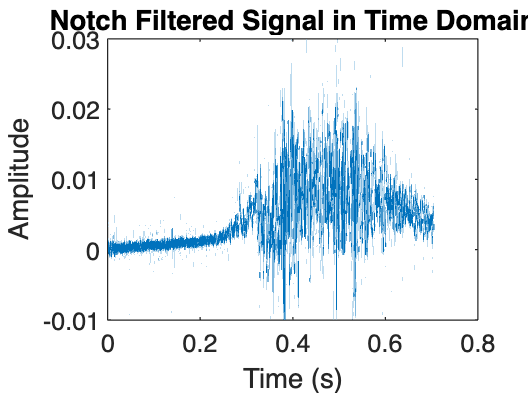


% Plot Time-Domain
t = (0:1/Fs:N/Fs-1/Fs)';
figure;
plot(t, dataFiltered)
title('Notch Filtered Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');

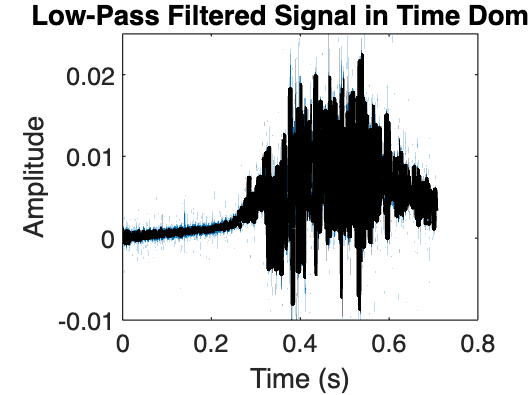


figure;
plot(t, data)
hold on 
plot(t, dataLowPass, 'LineWidth', 2, 'Color', 'k')
title('Low-Pass Filtered Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');
hold off

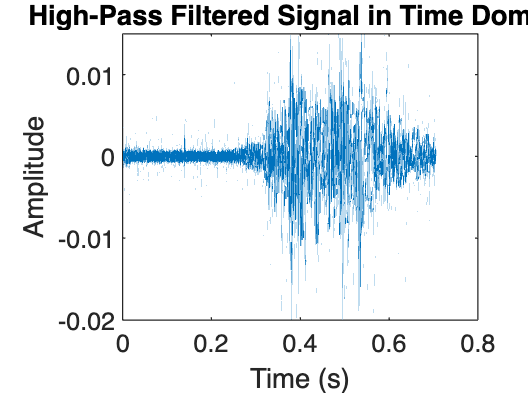


figure;
plot(t, dataHighPass)
title('High-Pass Filtered Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');

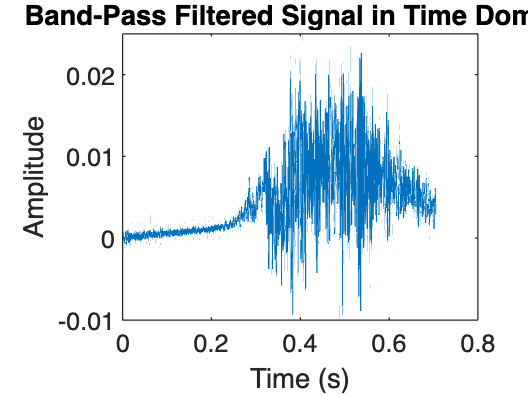


figure;
plot(t, dataBandPass)
title('Band-Pass Filtered Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');

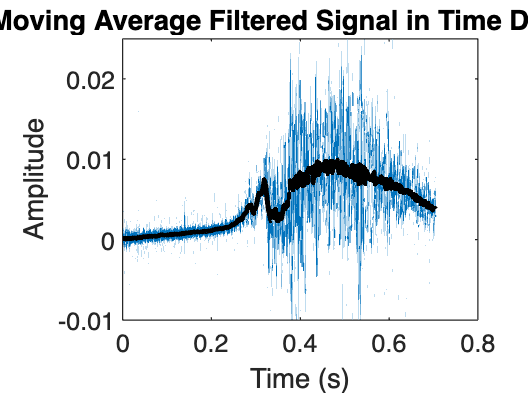


figure;
plot(t, data)
hold on
plot(t, dataMovingAvg, 'LineWidth', 2, 'Color', 'k')
title('Moving Average Filtered Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');
hold off


disp('Time-domain plots generated for all filters.');

Time-domain plots generated for all filters.



% Detect peak pressure for all methods
[peakOriginal, idxOriginal] = max(data); 
peakOriginalBar = peakOriginal;
timeOriginal = t(idxOriginal);

[peakFiltered, idxFiltered] = max(dataFiltered); 
peakFilteredBar = peakFiltered;
timeFiltered = t(idxFiltered);

[peakLowPass, idxLowPass] = max(dataLowPass); 
peakLowPassBar = peakLowPass;
timeLowPass = t(idxLowPass);

[peakHighPass, idxHighPass] = max(dataHighPass); 
peakHighPassBar = peakHighPass;
timeHighPass = t(idxHighPass);

[peakBandPass, idxBandPass] = max(dataBandPass); 
peakBandPassBar = peakBandPass;
timeBandPass = t(idxBandPass);

[peakMovingAvg, idxMovingAvg] = max(dataMovingAvg); 
peakMovingAvgBar = peakMovingAvg;
timeMovingAvg = t(idxMovingAvg);

% Display results in a table
methods = {'Original', 'Notch Filter', 'Low-Pass Filter', 'High-Pass Filter', 'Band-Pass Filter', 'Moving Average'};
peakPressures = [peakOriginalBar, peakFilteredBar, peakLowPassBar, peakHighPassBar, peakBandPassBar, peakMovingAvgBar];
peakTimes = [timeOriginal, timeFiltered, timeLowPass, timeHighPass, timeBandPass, timeMovingAvg];

resultsTable = table(methods', peakPressures', peakTimes', 'VariableNames', {'Method', 'PeakPressure_bar', 'Time_s'});
disp(resultsTable);

           Method           PeakPressure_bar    Time_s 
    ____________________    ________________    _______

    {'Original'        }        0.022906        0.53769
    {'Notch Filter'    }        0.022873        0.53769
    {'Low-Pass Filter' }        0.022401        0.53772
    {'High-Pass Filter'}         0.01396        0.53769
    {'Band-Pass Filter'}        0.022632        0.53772
    {'Moving Average'  }       0.0098859        0.48351




% Identify dominant frequency modes
Y = fft(data);
P2 = abs(Y/N);
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
frequencies_kHz = f(1:length(P1)-1)/1000;
[peaks, locs] = findpeaks(P1(1:end-1), 'MinPeakHeight', max(P1)*0.1);
dominantFrequencies = frequencies_kHz(locs);

% Display dominant frequency modes
disp('Dominant frequency modes (kHz):');

Dominant frequency modes (kHz):


disp(dominantFrequencies);

     5.6750e-003     8.5124e-003   201.4613e-003   245.4423e-003   259.6297e-003   275.2359e-003



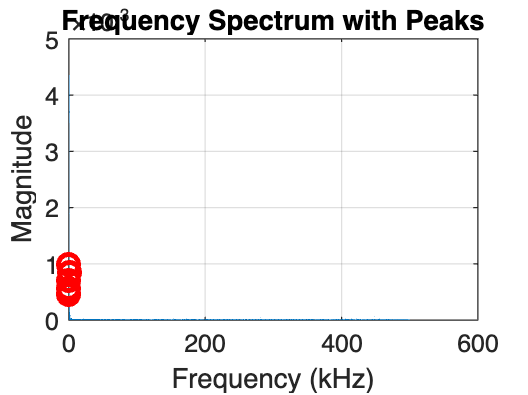


% Plot peaks on the frequency spectrum
figure;
plot(frequencies_kHz, P1(1:end-1));
hold on;
plot(frequencies_kHz(locs(:)), peaks(:), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
title('Frequency Spectrum with Peaks');
xlabel('Frequency (kHz)'); ylabel('Magnitude');
grid on;
hold off;

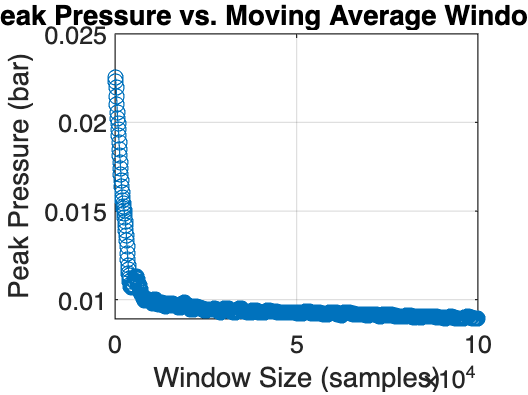


% Analyze peak pressure as a function of moving average window size
windowSizes = 100:100:100000;
peakPressures = zeros(size(windowSizes));
for i = 1:length(windowSizes)
    tempMovingAvg = movmean(data, windowSizes(i));
    peakPressures(i) = max(tempMovingAvg);
end

figure;
plot(windowSizes, peakPressures, '-o')
title('Peak Pressure vs. Moving Average Window Size')
xlabel('Window Size (samples)')
ylabel('Peak Pressure (bar)')
grid on;